# Data reduction with timeseries

This MATLAB live script was created for an REU tutorial in mathematical/computational neuroscience at Southern Methodist University in July 2022.  It introduces topics of interest in timeseries analysis and system reduction.  Anyone with background knowledge in differential equations, linear algebra, and MATLAB background can follow along.  It is accompanied by blackboard notes and discussion as part of a mini-tutorial.  Those notes and discussion are not included here, but with some reading and thinking the following examples illustrate the benefits of a delayed-coordinate approach to analyzing timeseries data.  Since this was written as a live script, there are likely abundant spelling errors/typos.

When I think of the combination of delay coordinates with reduction techniques, I think of the lyric "..once in a while, you get shown the light in the strangest of places if you look at it right..." ([Scarlet Begonias, #13](https://archive.org/details/gd77-05-08.sbd.hicks.4982.sbeok.shnf/gd77-05-08eaton-d2t04.shn)).  It fits the spirit of timeseries data like those obtained from neural data.  It can look messy or un-insightful, but with appropriately justified methods, a signal's mysteries can be uncovered.

## 1 Time-delay coordinates with the unit circle

In this section, you will create a function `build_delay_coordinates()`.  Its inputs will be a timeseries of observations, the associated time points, the number of delays, and the number of steps in between successive delays.  It will return the constructed delay coordinates and corresponding time points.  Now would be a good time to create a separate function .m file with this name and write your routine.

With this function, you will analyze different reconstructions of the unit circle using only a timeseries of data obtained from the $x$-coordinate of a trajectory following the circle.  First, recall the delay-coordinate formulation (discussed as a group).  Suppose we have some collection of state variables that depend on time, $x(t)\in\mathbb{R}^n$.  We may not be able to observe these variables directly.  Instead we only have access to a timeseries output of observation function $y(t) = g(x(t))\in\mathbb{R}^m$.  Here $g\colon \mathbb{R}^n\rightarrow\mathbb{R}^m$, and the outputs $y\in\mathbb{R}^m$ are a timeseries of data.


$$y(t)\mapsto\left[y(t), y(t - \tau), y(t - 2\tau),\dots,y(t - s\tau)\right]\in\mathbb{R}^{m\times(s+1)}$$


If the trajectory $x(t)$ evolves along a manifold $\mathcal{M}$ (a geometric object, loosely) of dimension $d$, $\mathcal{M}\subseteq\mathbb{R}^{d}$, then according to a theorem by Takens [[Takens, 1981](https://www.crcv.ucf.edu/gauss/info/Takens.pdf)] ([Technical report; gives more background](http://eprints.maths.manchester.ac.uk/175/1/embed.pdf)), for a nice enough observation function $g$, we can obtain an object qualitatively equivalent to $\mathcal{M}$ provided $m\times(s+1)>2d$. Roughly speaking, a smoothly deformed version of $\mathcal{M}$ can be recreated in a higher-dimensional space by appending sufficient delays.

To get working with delay coordinates, we first generate a timeseries of data along the unit circle with the parametrization

$(x_1(t), x_2(t)) = \left(\cos(2\pi t),\sin(2\pi t)\right)$.  

Notice the factor of $2\pi$ ensures 1 rotation around the unit circle from $t=0$ to $t=1$.  If we use unit in time, this corresponds to a frequency of $1\,\mathrm{Hz}$.  Then we use the observation function $g\colon\mathbb{R}^2\rightarrow\mathbb{R}$ defined as 

$g(x_1,x_2) = x_1$.  

In other words, we are only observing the first coordinate's forward evolution in time.  Read/understand/run the following code to generate one rotation around the unit circle.

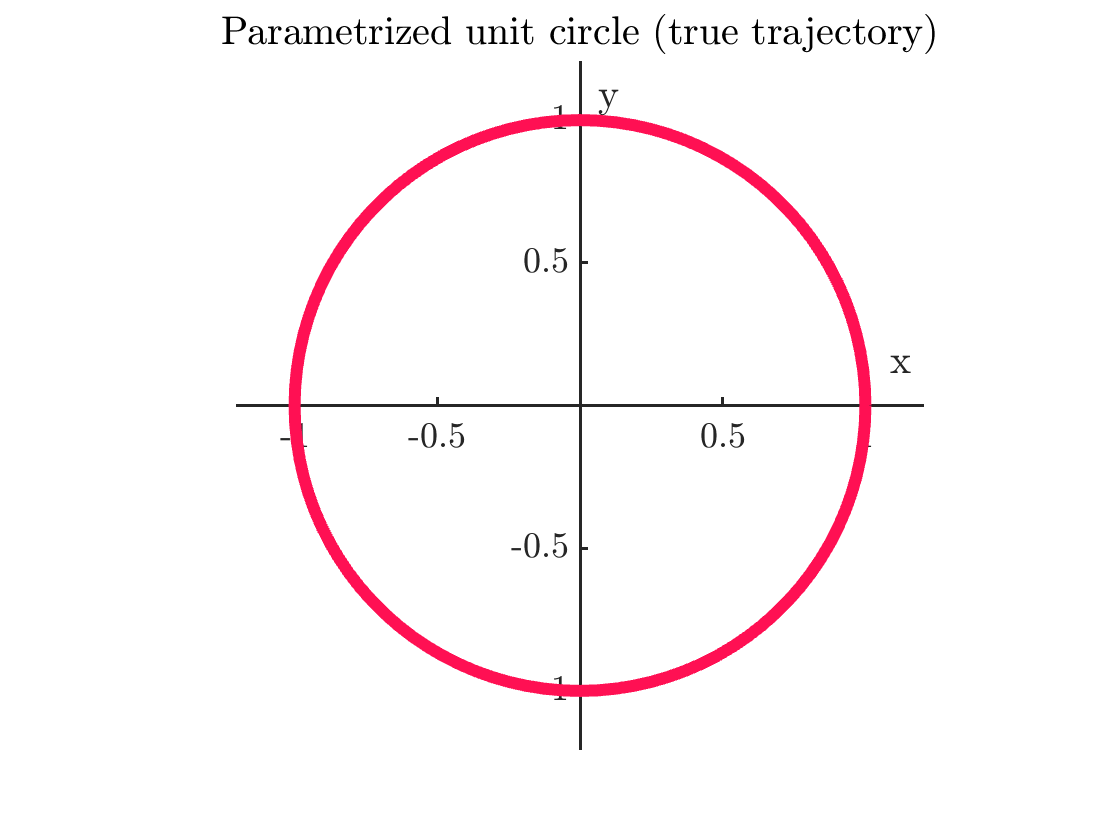

% Clear workspace for this section
clear; clc; obs_color = [255 16 83]./255; emb_color = [89 195 195]./255; % colors
% set up time constraints
t0 = 0; % initial time
tf = 1; % final time
dt = 0.01; % time step

% span 1 second spaced at dt
t = t0 : dt : tf;

% parametrize circle at rate 1 Hz
x1 = cos( 2*pi*t );
x2 = sin( 2*pi*t );

% plot the circle
figure
plot(x1,x2, 'Color', obs_color, 'LineWidth', 6)
xlabel('x')
ylabel('y')
title('Parametrized unit circle (true trajectory)')

% prettify
ax = gca;
ax.XAxisLocation = 'origin'; % axis at origin
ax.YAxisLocation = 'origin'; % axis at origin
ax.FontSize = 18;            % make fontsize bigger
ax.LineWidth = 1.5;          % a little thicker lines
xlim([-1 1] + [-1 1].*2*0.1) % padd axis
ylim([-1 1] + [-1 1].*2*0.1) % padd axis
box off
pbaspect([1 1 1])

As previously mentioned, with delay coordinates, however, we do not necessarily observe the *circle*.  Instead, for some (usually scientific) reason, we only observe the $x_1$ coordinate, so let's plot that.

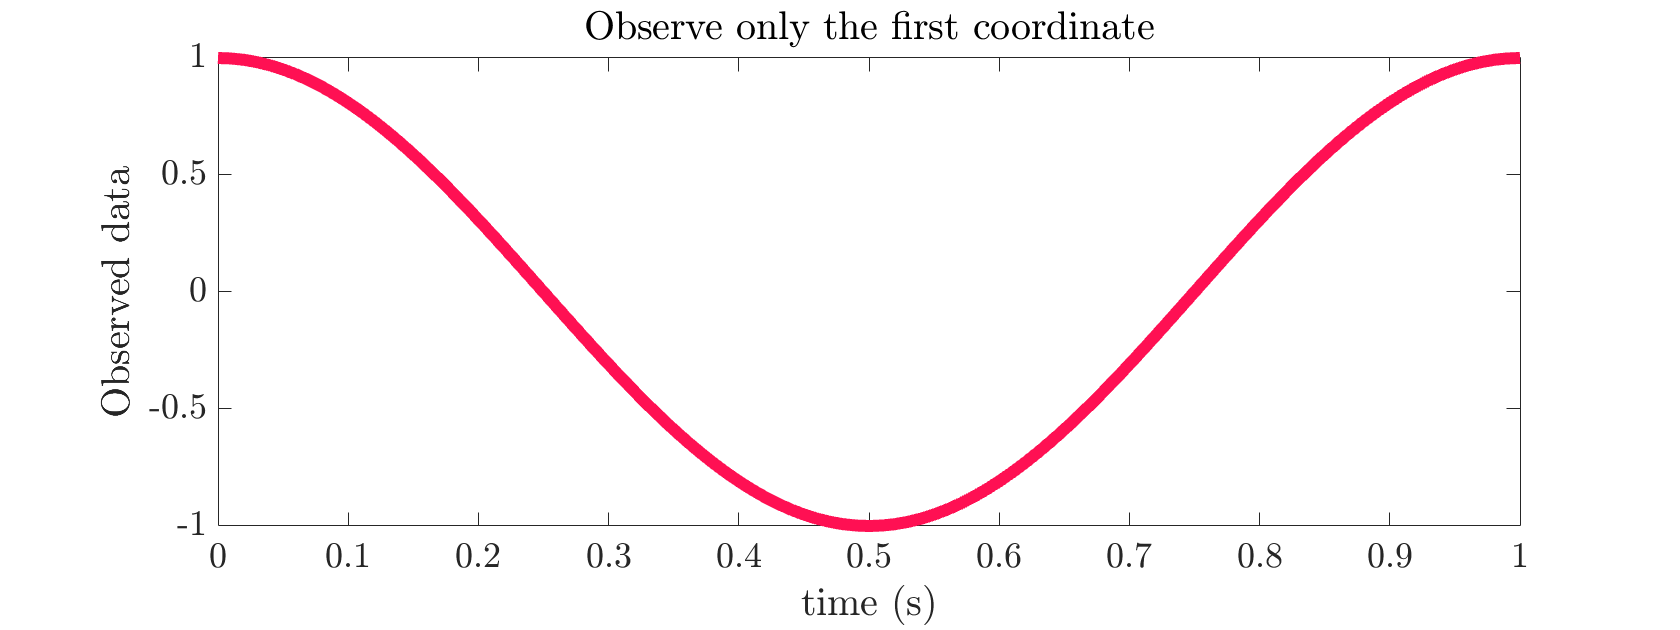

y = x1; % notation--y represents the observed data

figure
plot(t, y, 'LineWidth', 6, 'Color', obs_color)

% labels
xlabel('time (s)')
ylabel('Observed data')
title('Observe only the first coordinate')

% Prettify
ax = gca;
ax.FontSize = 18;
cf = gcf;
cf_pos = cf.Position;
cf.Position = [cf_pos(1:2), 1.5*cf_pos(3), 0.75*cf_pos(4)];

### Task 1.1: Get delay coordinates working properly

In our formulation, the delay-coordinates have two main parameters: $\tau$ and $s$.  Recall that we used $\tau$ to represents the time-step between delays and $s$ represents the number of delays.  Since we only work with data sampled at discrete time points separated by $\Delta t$ (represented by the variable `dt`) , we have to consider the sampling rate when we set $\tau$.

For example, suppose we want to build 2-dimensional delayed coordinates separated by $0.05\,\mathrm{s}$.  Since we have set $\Delta t = 0.01$ (or `dt=0.01` in code), we would have to set $\tau = 5$, so that $\Delta t \times \tau = 0.01 \times 5 = 0.05$.  Note that this formulation is based on *my* formulation of the delay-coordinate function.  To *me* it made the most sense to have knowledge of a sampling rate $\Delta t$ and in code set $\tau$ to be the *number* of steps at $\Delta t$.

#### Prompt 1.1.1: Using your `build_delay_coordinates()` function, 2-dimensional delay coordinates from the observation $x_1$ that are separated by $0.1\,\mathrm{s}$.  Plot your delay-generated data and original circle on the same axis

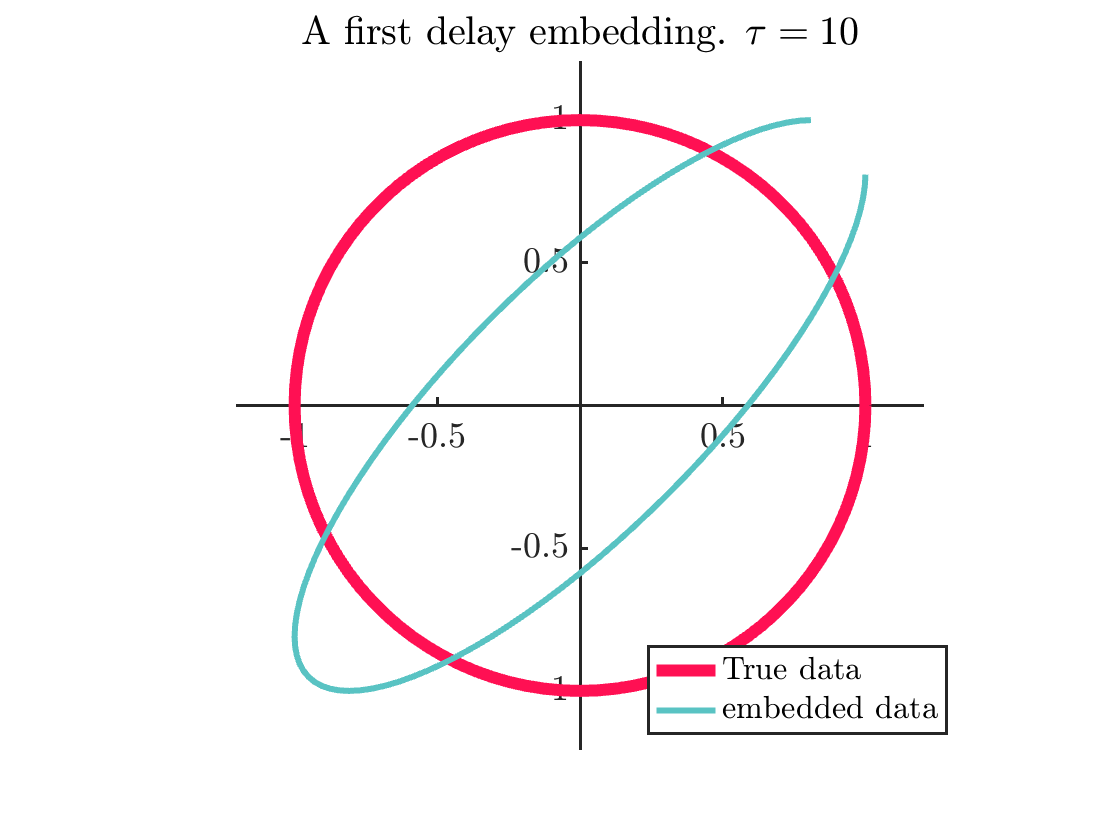

%           Your Code goes Here         %

tau = 10;    % time between delays
s   = 1;     % number of delays

% you need to write build_delay_coordinates()
[X_delay, ~] = build_delay_coordinates(x1', t, s, tau);

% plot the circle
figure
hold on
plot(x1,x2, 'Color', obs_color, 'LineWidth', 6)
plot(X_delay(:,1), X_delay(:,2), 'Color', emb_color, 'LineWidth', 3, 'LineStyle',"-")
title(sprintf('A first delay embedding. $\\tau=%d$', tau), ...
    'Interpreter','latex')
legend('True data', 'embedded data', 'Location', 'best')

% prettify
ax = gca;
ax.XAxisLocation = 'origin'; % axis at origin
ax.YAxisLocation = 'origin'; % axis at origin
ax.FontSize = 18;            % make fontsize bigger
ax.LineWidth = 1.5;          % a little thicker lines
xlim([-1 1] + [-1 1].*2*0.1) % padd axis
ylim([-1 1] + [-1 1].*2*0.1) % padd axis
box off
pbaspect([1 1 1])

### Task 1.2: A degenerate delay at the observation's period

You probably notice that the starting and ending point of your embedded data don't meet.  This is because the first $s \times \tau$ sampled points have insufficient history to append for a proper delay coordinate.  For example, the fourth sampled time point corresponds to $t = 0 + \Delta t \times (4 - 1) = 0 + 0.01\times 3 = 0.03\,\mathrm{s}$.  But, if we want to add a lag spanning $0.1\,\mathrm{s}$, we would need to have access to data sampled previous to the first time point at $t=0$.

Let's remove this artifact by observing more rotations of the circle by generating data through two periods, i.e., for two seconds.

% set up time constraints
t0 = 0; % initial time
tf = 2; % final time
dt = 0.01; % time step

% span 2 seconds spaced at dt
t = t0 : dt : tf;

% parametrize circle at rate 1 Hz
x1 = cos( 2*pi*t )'; % make it a vector [nrows 1]
x2 = sin( 2*pi*t )'; % make it a vector [nrows 1]

You can re-plot your delayed-data if you would like to visualize the embedding with starting and ending aligned.

Since we know our true underlying data comes from the unit circle, we can actually derive an *exact copy *of the data with delay coordinates

#### Prompt 1.2.1: Find a value of $\tau$ so that a 2-dimensional delay coordinate can exactly reconstruct the unit circle

*Hint: Consider the relationship between sine and cosine in terms of shifts in angle.*

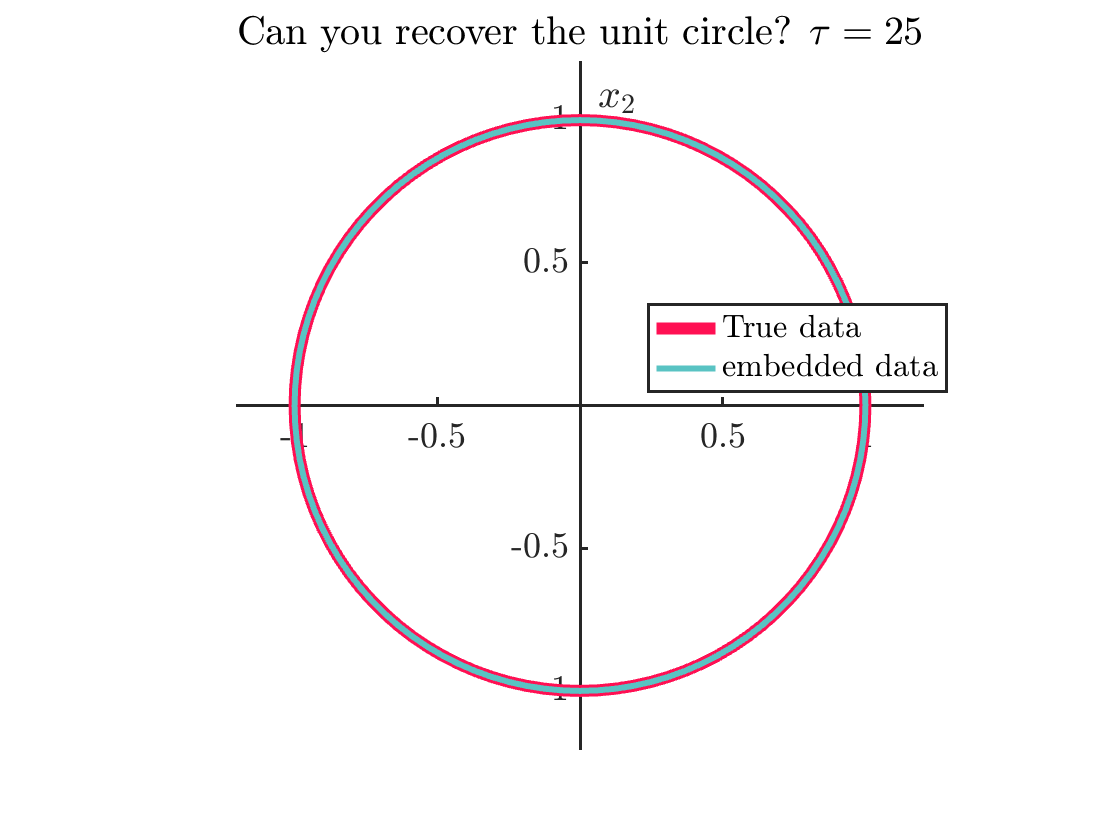

%           Your Code goes Here         %

tau = 25; % delay step
s   = 1;  % number of delays

% you need to write build_delay_coordinates
[X_delay, ~] = build_delay_coordinates(x1, t, s, tau);

% plot the circle
figure
hold on
%%% true data %%%
plot(x1,x2, 'Color', obs_color, 'LineWidth', 6)

%%% delayed data %%%
plot(X_delay(:,1), X_delay(:,2), 'Color', emb_color, 'LineWidth', 3, 'LineStyle','-')

xlabel('$x_1$', 'Interpreter', 'Latex')
ylabel('$x_2$', 'Interpreter', 'Latex')
title(sprintf('Can you recover the unit circle? $\\tau=%d$', tau), ...
        'Interpreter', 'latex')
legend('True data', 'embedded data', 'Location', 'best')

% prettify
ax = gca;
ax.XAxisLocation = 'origin'; % axis at origin
ax.YAxisLocation = 'origin'; % axis at origin
ax.FontSize = 18;            % make fontsize bigger
ax.LineWidth = 1.5;          % a little thicker lines
xlim([-1 1] + [-1 1].*2*0.1) % padd axis
ylim([-1 1] + [-1 1].*2*0.1) % padd axis
box off
pbaspect([1 1 1])

### Prompt 1.2.2: Set $\tau=50$ and plot the delayed data.  What do you observe? Can you explain mathematically your observation?  What does this imply about delay coordinates?

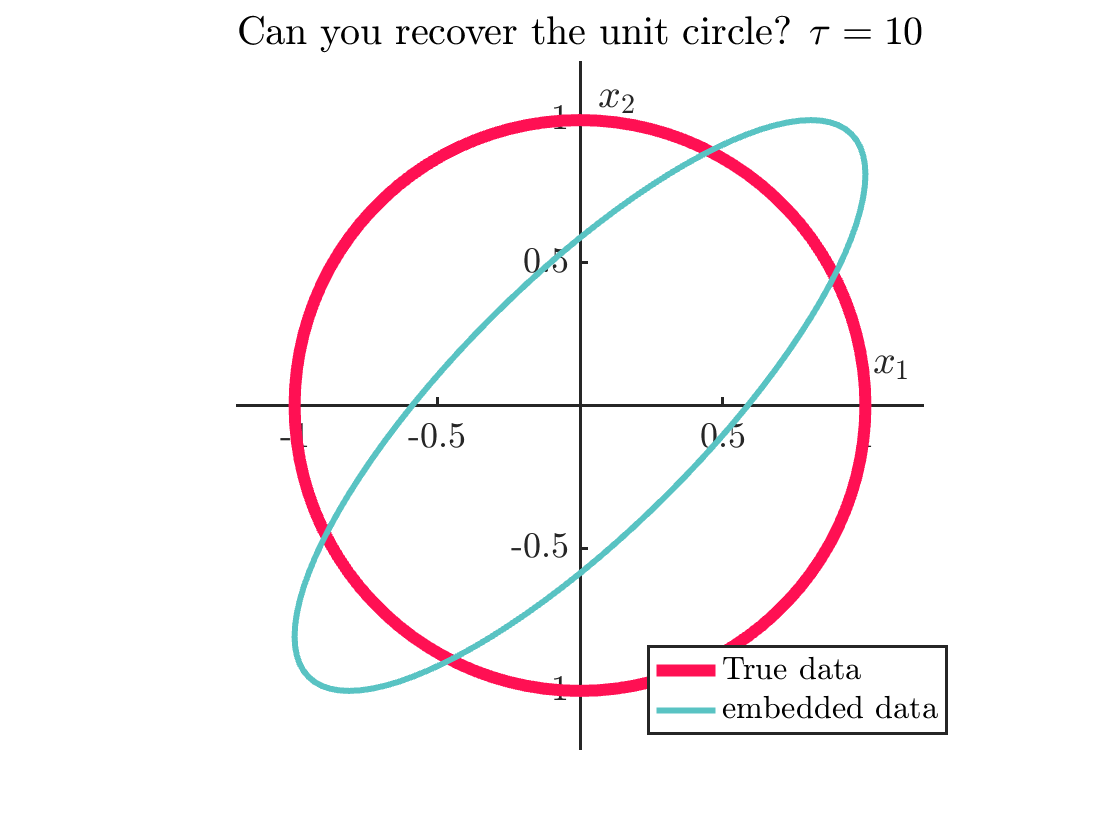

%           Your Code goes Here         %

tau = 10; % delay step
s   = 1;  % number of delays

[X_delay, ~] = build_delay_coordinates(x1, t, s, tau);

% plot the circle
figure
hold on
%%% true data %%%
plot(x1,x2, 'Color', obs_color, 'LineWidth', 6)

%%% delayed data %%%
plot(X_delay(:,1), X_delay(:,2), 'Color', emb_color, 'LineWidth', 3, 'LineStyle','-')

xlabel('$x_1$', 'Interpreter', 'Latex')
ylabel('$x_2$', 'Interpreter', 'Latex')
title(sprintf('Can you recover the unit circle? $\\tau=%d$', tau), ...
        'Interpreter', 'latex')
legend('True data', 'embedded data', 'Location', 'best')

% prettify
ax = gca;
ax.XAxisLocation = 'origin'; % axis at origin
ax.YAxisLocation = 'origin'; % axis at origin
ax.FontSize = 18;            % make fontsize bigger
ax.LineWidth = 1.5;          % a little thicker lines
xlim([-1 1] + [-1 1].*2*0.1) % padd axis
ylim([-1 1] + [-1 1].*2*0.1) % padd axis
box off
pbaspect([1 1 1])

Since we sample at $\Delta t = 0.01$, setting $\tau = 50$, makes a skip equal to $\Delta t \times \tau = 0.01 \times 50 = 0.5\,\mathrm{s}$.  With frequency $1\,\mathrm{Hz}$ this corresponds to half a rotation around the circle, and so $\cos(2\pi(t-0.5)) = -\cos(2\pi t)$.  This parametrized the line $(x(t), -x(t))$, which is a straight line with slope equal to negative one.  This is a degenerate case where the embedding fails due to the periodicity of the data.  In practice, one must consider such degeneracies.

### Task 1.3: Sometimes a 2D embedding isn't enough

So far, we have used the observation function $g(x_1,x_2) = x_1$.  This is a simple observation function, but we were able to explore what embeddings can look like, how they relate to the original data, and some degeneracies in the data that can impede the effectiveness of delays.

This time, lets say we have a non-linear observation function $g(x_1,x_2) = x_1^3 - \frac{1}{3}x_2^3 + x_1x_2$.  

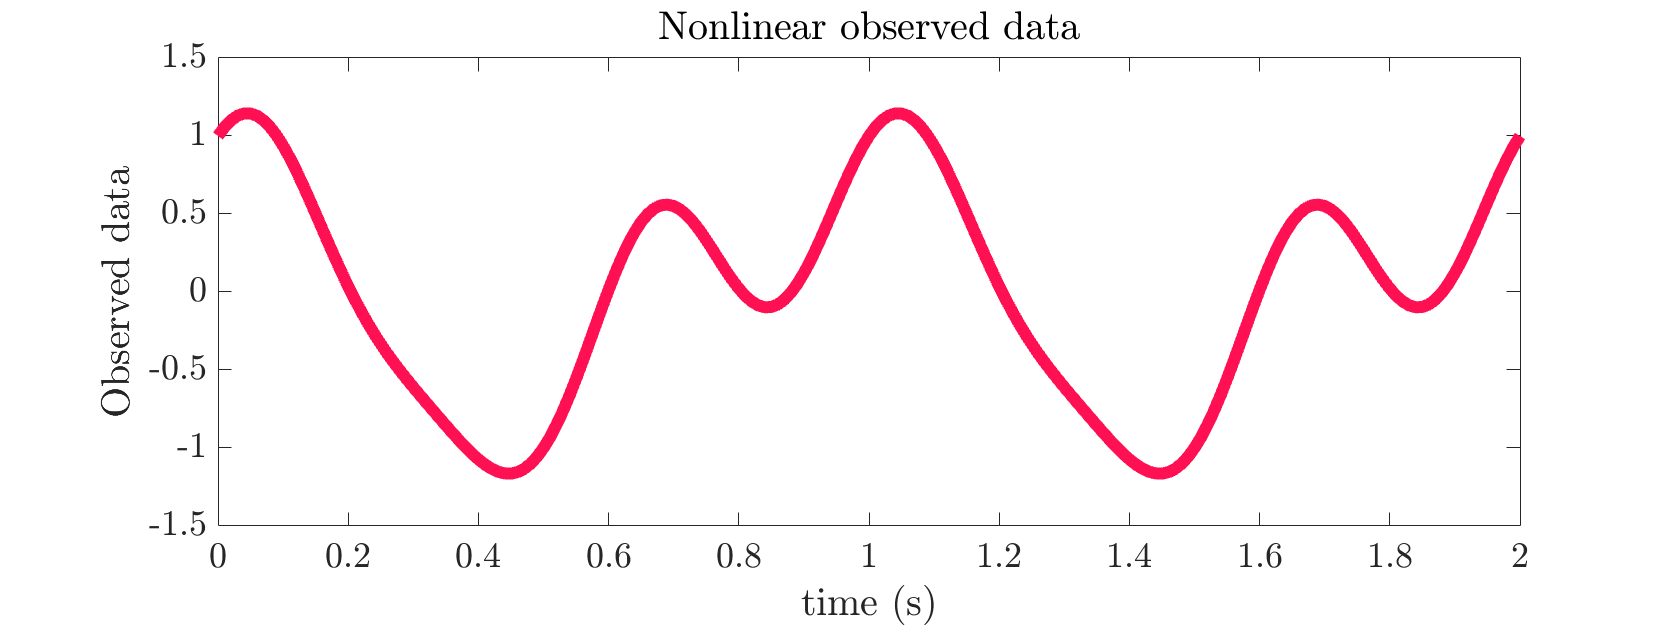

g = @(x1, x2) x1.^3 - (1/3)*x2.^3 + x1.*x2; % observation function
y = g(x1, x2);                              % output of observation
figure
plot(t, y, 'LineWidth', 6, 'Color', obs_color)

% labels
xlabel('time (s)')
ylabel('Observed data')
title('Nonlinear observed data')
% Prettify
ax = gca;
ax.FontSize = 18;
cf = gcf;
cf_pos = cf.Position;
cf.Position = [cf_pos(1:2), 1.5*cf_pos(3), 0.75*cf_pos(4)];

In this case, the data *looks *like it could come from some type of periodic or oscillatory process, but its connection to the unit circle is not (at least to me) immediately and obviously true.

#### Prompt 1.3.1: Set $\tau=10$ and plot 2-dimensional delayed data.  What do you notice?  If your embedding was made of Play-doh could you shape it into a circle?

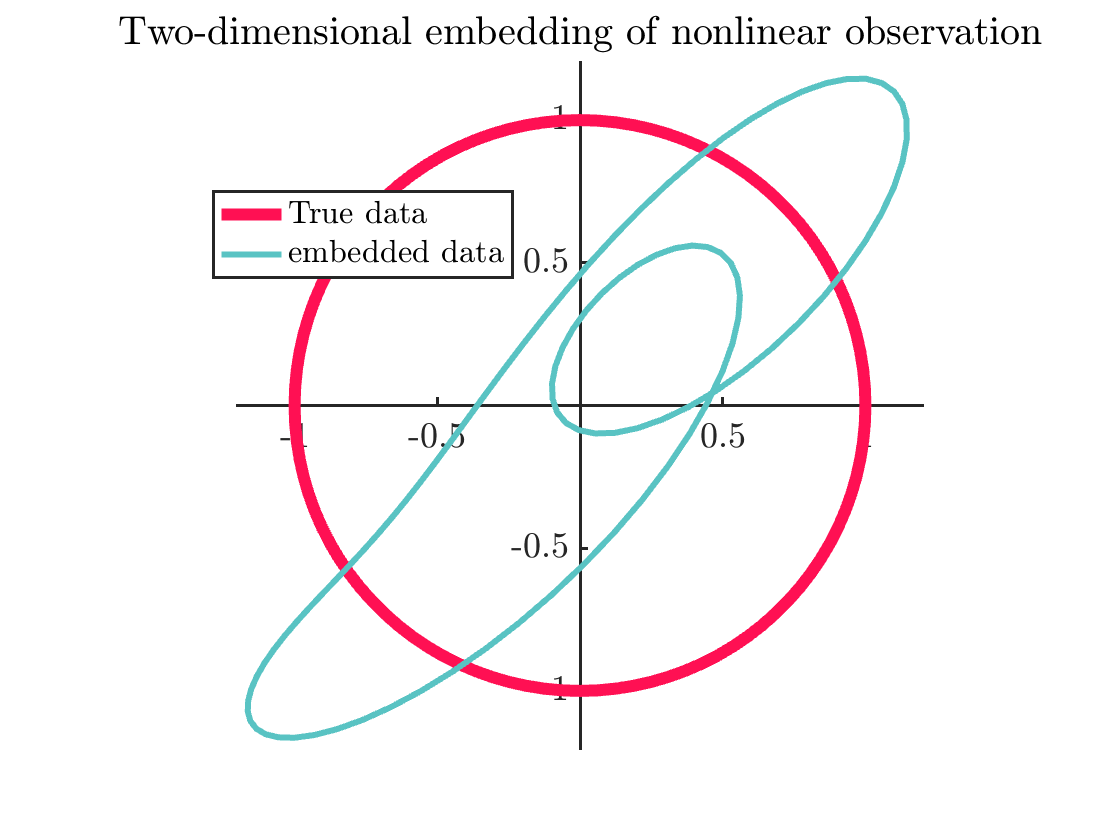

%           Your Code goes Here         %

tau = 5;
s   = 1;

[X_delay, ~] = build_delay_coordinates(y, t, s, tau);

% plot the circle
figure
hold on
plot(x1,x2, 'Color', obs_color, 'LineWidth', 6)
plot(X_delay(:,1), X_delay(:,2), 'Color', emb_color, 'LineWidth', 3, 'LineStyle','-')
title('Two-dimensional embedding of nonlinear observation')
legend('True data', 'embedded data', 'Location', 'best')

% prettify
ax = gca;
ax.XAxisLocation = 'origin'; % axis at origin
ax.YAxisLocation = 'origin'; % axis at origin
ax.FontSize = 18;            % make fontsize bigger
ax.LineWidth = 1.5;          % a little thicker lines
xlim([-1 1] + [-1 1].*2*0.1) % padd axis
ylim([-1 1] + [-1 1].*2*0.1) % padd axis
box off
pbaspect([1 1 1])

Now, it *could* be that you can make the embedding look more like a circle by changing $\tau$.  Go ahead and try it.  Alternatively, we can consider the statement of [Takens's](https://en.wikipedia.org/wiki/Takens%27s_theorem) theorem and the dimension of our underlying manifold $\mathcal{M}\subseteq \mathbb{R}^d$.  To *guarantee* the delay coordinates give an embedded qualitative copy of the underlying manifold (the unit circle in this example) for *any* value of $\tau$ and any regular function $g$, we need to ensure that the dimension of our delay coordinates are *strictly larger* than twice the dimension of the true manifold. 

In particular, the unit circle is a 1-dimensional manifold within $\mathbb{R}^2$. To guarantee a qualitative copy of the circle, the embedded dimension needs to be at least 3 ($3 \geq 2 \times 1$).  Note that this condition is sufficient, but not necessary, and we have seen previous examples where an embedding dimension of 2 exactly reconstructed the unit circle.

#### Prompt 1.3.2: Set $\tau=10$ and plot 3-dimensional delayed data.  What do you notice?  If your embedding was made of Play-doh could you shape it into a circle?

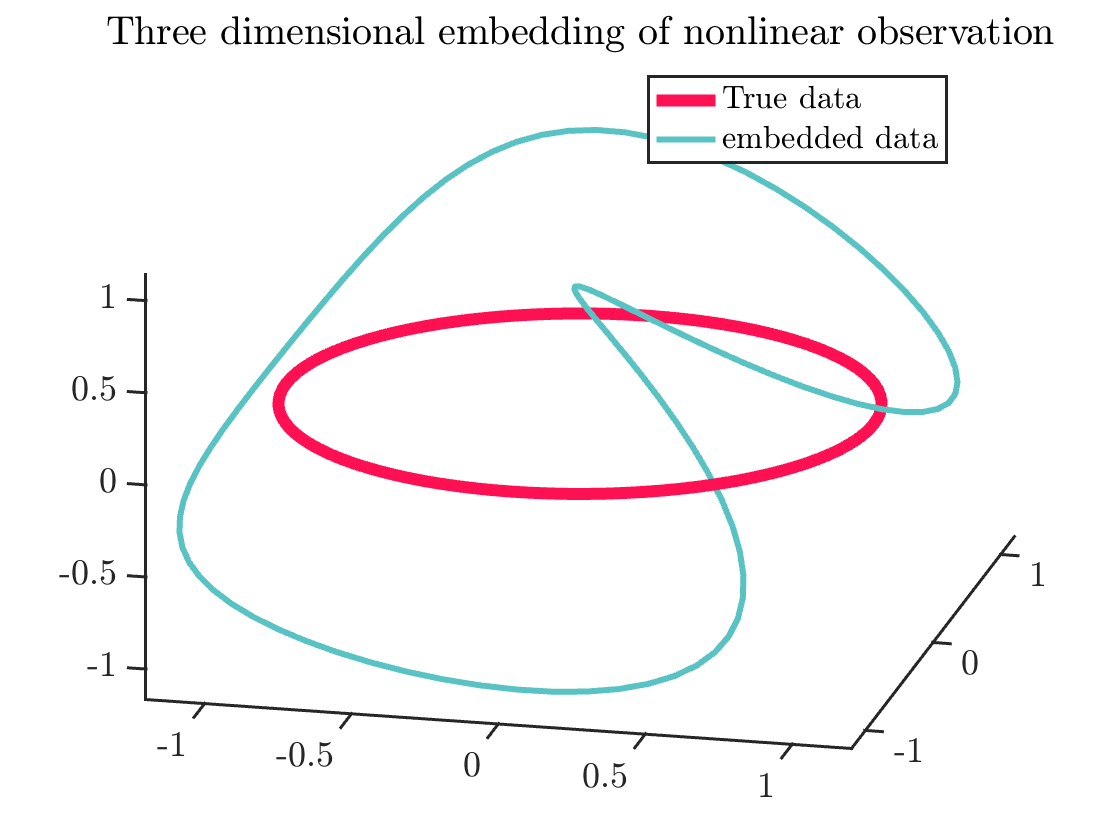

%           Your Code goes Here         %

tau = 10;
s   = 2;

[X_delay, ~] = build_delay_coordinates(y, t, s, tau);

% plot the circle
figure
hold on
plot3(x1,x2,zeros(size(x1)), 'Color', obs_color, 'LineWidth', 6)
plot3(X_delay(:,1), X_delay(:,2), X_delay(:,3), 'Color', emb_color, 'LineWidth', 3, 'LineStyle','-')
title('Three dimensional embedding of nonlinear observation')
legend('True data', 'embedded data', 'Location', 'best')

% prettify
ax = gca;
ax.FontSize = 18;            % make fontsize bigger
ax.LineWidth = 1.5;          % a little thicker lines
xlim([-1 1] + [-1 1].*2*0.1) % padd axis
ylim([-1 1] + [-1 1].*2*0.1) % padd axis
box off
view([13 27])

#### Writing Prompt: Write a short abstract summarizing aspects of delay coordinates demonstrated in this section.

## 2 Time-delay coordinates with a noisy Lorenz attractor

The [Lorenz-63](https://en.wikipedia.org/wiki/Lorenz_system) model is an illustrative example of a 3-dimensional system of differential equations that exhibit chaos.  Although the system is deterministic (meaning given any initial condition we can predict the exact location of a trajectory at any point in time), it is characterized as chaotic due to its sensitivity on initial conditions.  That is to say, any two trajectories with arbitrarily close initial conditions will fail to remain close as time progresses.  The system of differential equations are given by


$$\begin{array}{rcl} \dot{x_1} &=& \sigma(x_2-x_1)\\ \dot{x_2}&=& x_1(\rho-x_3)-x_2\\ \dot{x_3} &=& x_1x_2 - \beta x_3\end{array}$$


Interestingly, this system only contains two nonlinear terms, yet for certain parameter regimes, it exhibits chaos.  We will use the parameters for the so-called Lorenz-63 model with


$$\sigma = 10, \quad \beta = 8/3, \quad \rho = 28.$$


We use the Lorenz example because trajectories are characterized by their evolution along a low-dimensional attractor.  That is, although trajectories are chaotic, their long-time behavior tends towards a particular region/object in phase-space, much like trajectories in a stable linear system to the origin.  But this attracting object, called a [strange attractor](https://www.dynamicmath.xyz/strange-attractors/), is non-trivial and difficult to describe analytically with explicit equations.  While we will not attempt to describe this region, we will see examples of its reconstruction from timeseries observations.  Run the below code to simulate the Lorenz system

% Add paths so we can generate data
addpath( genpath('./dataBuilders') )

clear; clc; % clear up for this section
%% Lorenze
% main tuning parameter is noise
noise_multiplier = 0; % 0 for no noise will modify later

% time set up
t0 = 0;
tf = 100;
dt = 0.01;


[X, t] = build_lorenz_data( noise_multiplier, [t0 tf], dt );



** Finished Lorenz simulation**



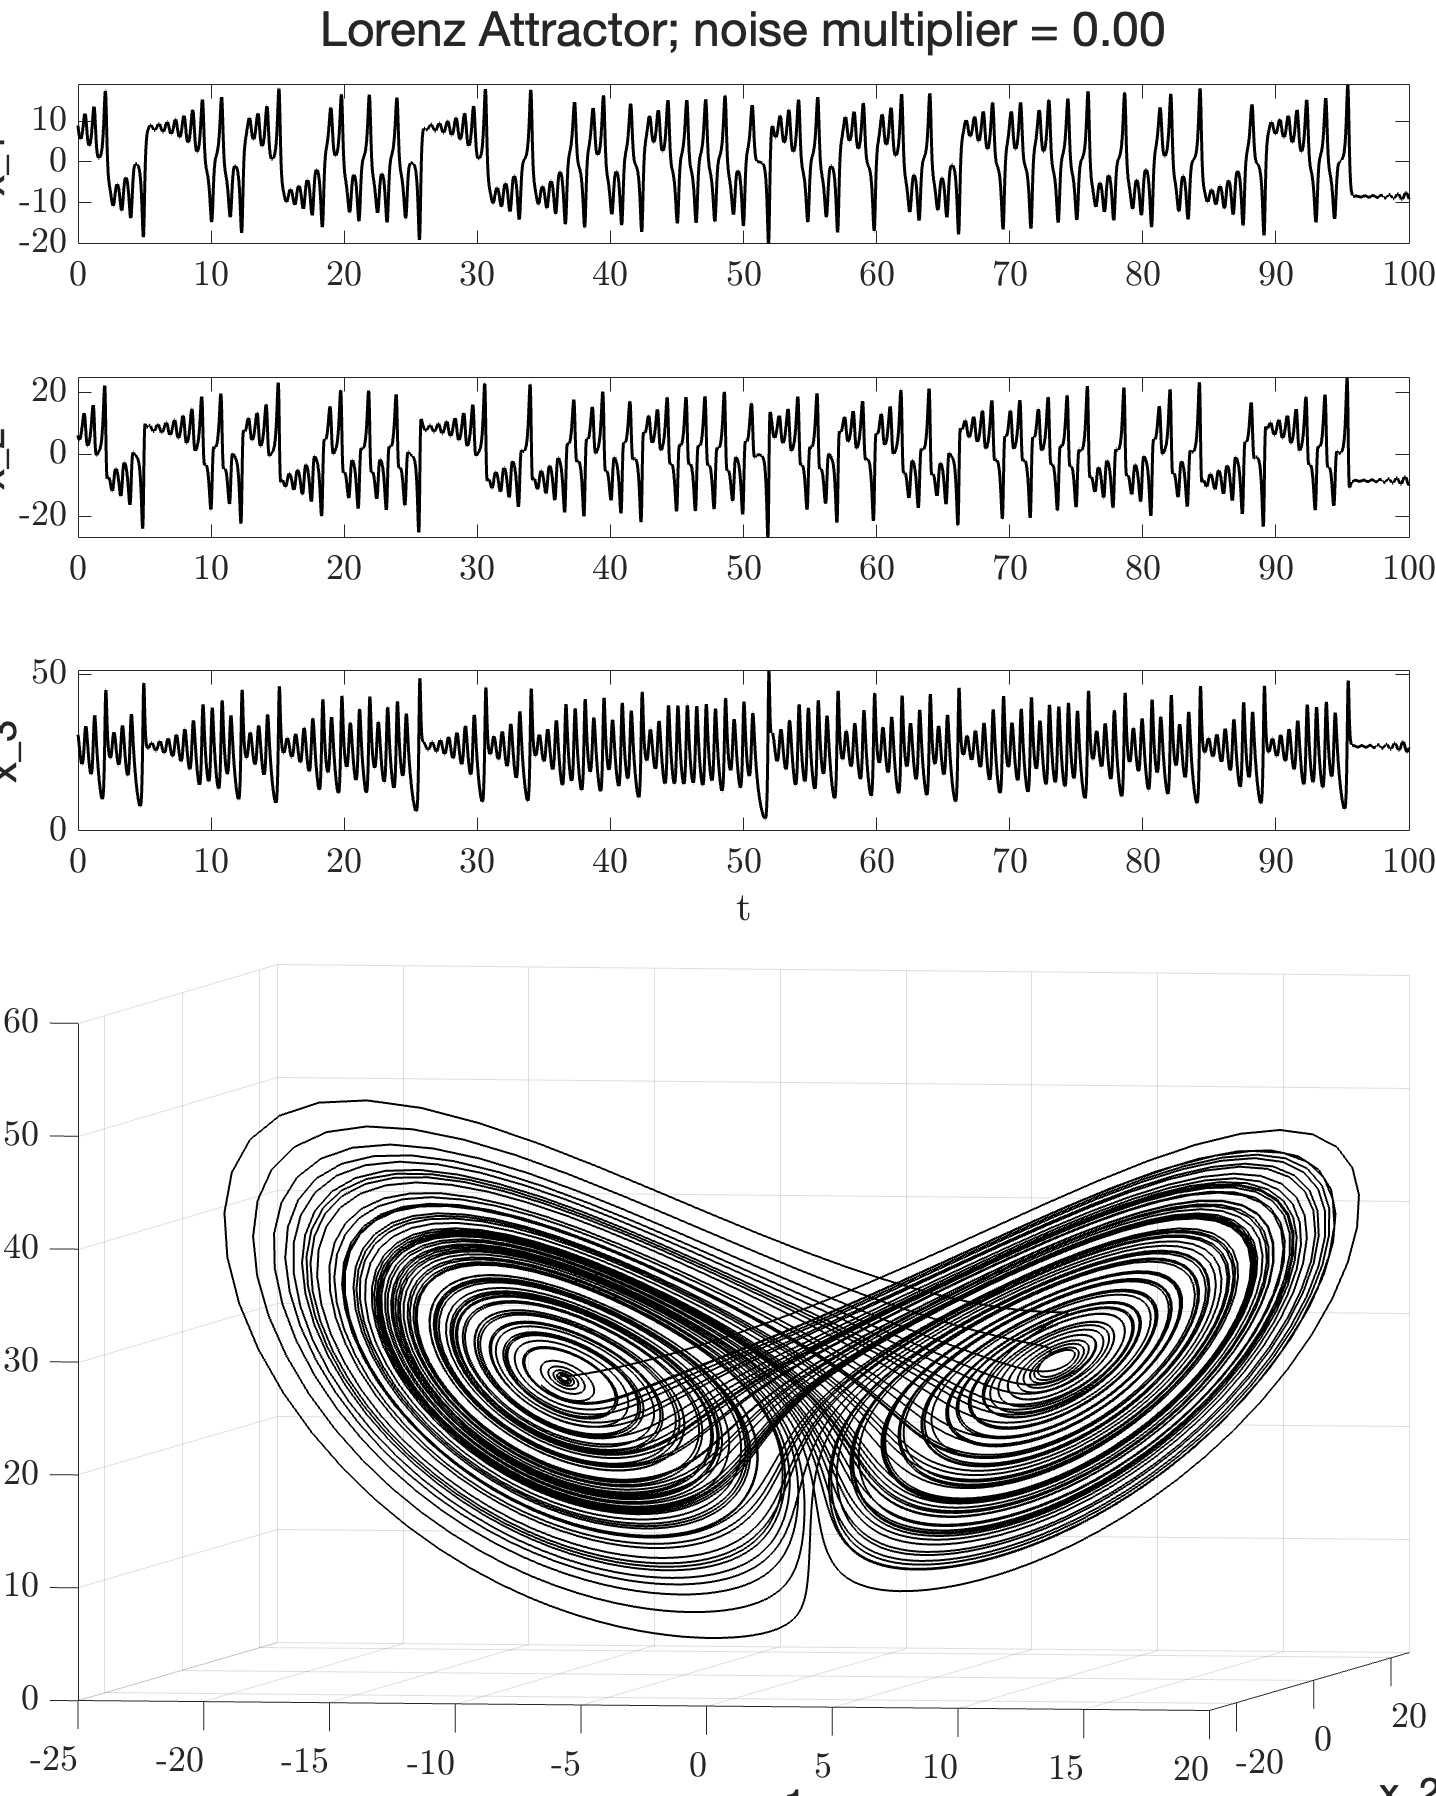

% Extract variables
x1 = X(:,1); % x1 <---> first column 
x2 = X(:,2); % x2 <---> second column
x3 = X(:,3); % x3 <---> third column

figure
lorenz_tiles = tiledlayout(6,4);

% Plot time by x
nexttile(1, [1 4])
plot(t, x1, ...
    'Color', 'k', ...
    'LineWidth', 1.5)
ylabel('x_1')
ax = gca;
ax.FontSize = 18;

% Plot time by y
nexttile(5, [1 4])
plot(t, x2, ...
    'Color', 'k', ...
    'LineWidth', 1.5)
ylabel('x_2')
ax = gca;
ax.FontSize = 18;

% Plot time by z
nexttile(9, [1 4])
plot(t, x3, ...
    'Color', 'k', ...
    'LineWidth', 1.5)
xlabel('t')
ylabel('x_3')
ax = gca;
ax.FontSize = 18;

% plot 3D timeseries as a trajectory
nexttile(13,[3 4] )
plot3(x1, x2, x3, ...
      'LineWidth', 1, ...
      'Color', [0 0 0])
grid on
xlabel('x_1')
ylabel('x_2')
zlabel('x_3')
view([10 5])
ax = gca;
ax.FontSize = 18;
lorenz_tiles.TileSpacing = 'compact';
lorenz_tiles.Title.String = sprintf('Lorenz Attractor; noise multiplier = %0.2f', noise_multiplier);
lorenz_tiles.Title.FontSize = 24;
lorenz_tiles.Padding = 'none';
% get screen size inf
screensize = get( 0, 'ScreenSize');
set(gcf, 'Position', [screensize(3)/2 0 screensize(3)/2 screensize(4)]);

### Task 2.1: Embed a noisy Lorenz attractor, with only a few delays

Let's take our circle example and choose as an initial observation function $g(x_1,x_2,x_3) = x_2$.  So, we pick-off the second coordinate (see previous plot for $x_2$), and that's our timeseries observation.

#### Prompt 2.1.1: Set $\tau=10$ and plot a two-dimensional embedding.  What do you oberve?

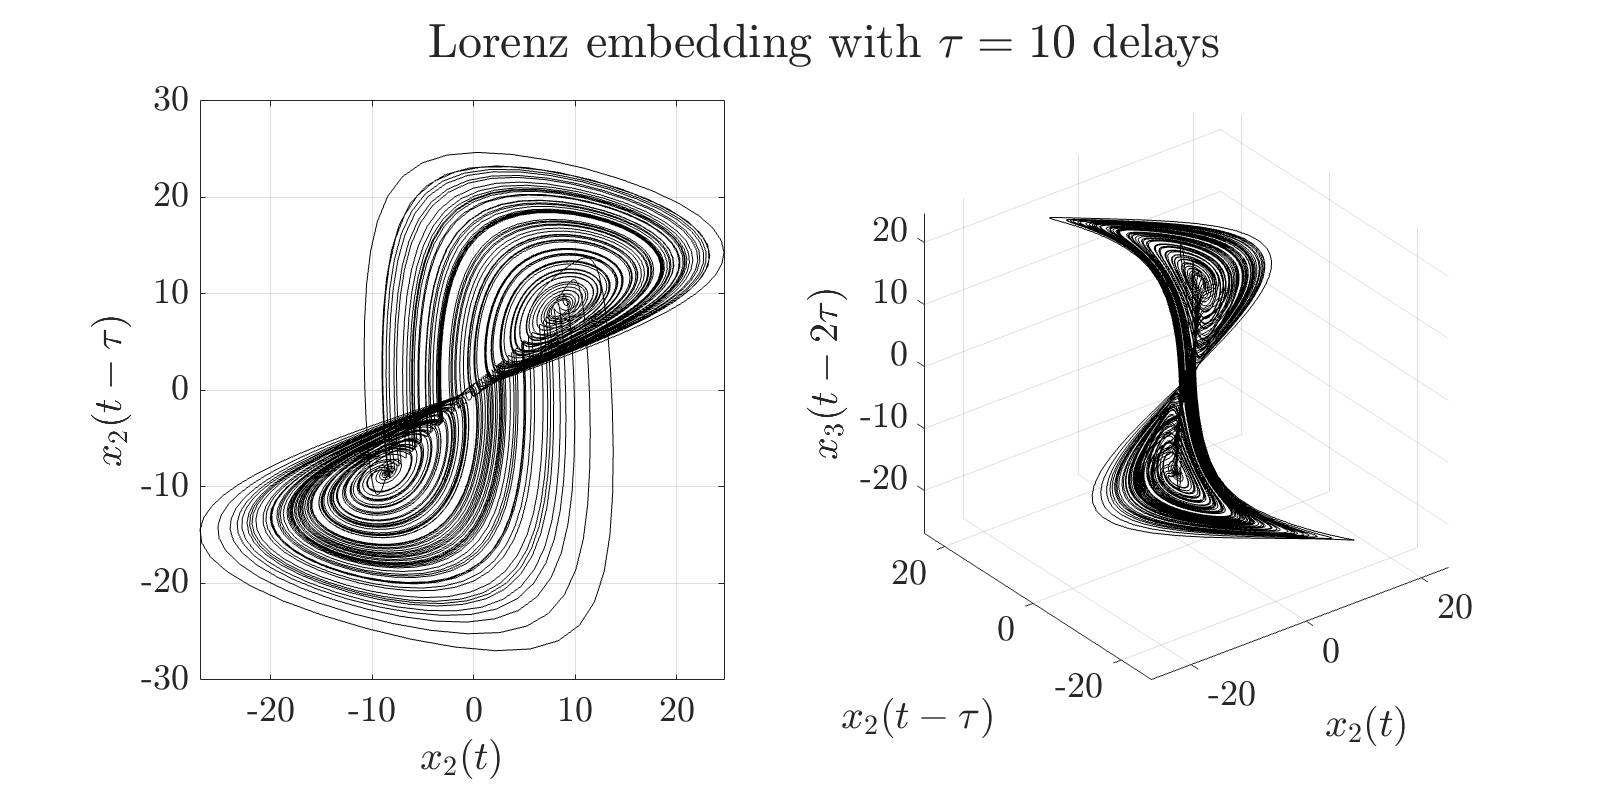

%           Your Code goes Here         %

tau = 10;   % timesteps to skip
s   = 2;    % number of delays

y = x2;     % y = g(x1,x2,x3) := x2
[X_delay, ~] = build_delay_coordinates(y, t, s, tau);

figure
lor_emb_sub = tiledlayout(1,2);

% 2D-plot
nexttile;
plot(X_delay(:,1), X_delay(:,2), 'Color', [0 0 0 0.5])
xlabel('$x_2(t)$', 'Interpreter','latex')
ylabel('$x_2(t-\tau)$', 'Interpreter','latex')
grid on
set(gca, 'FontSize', 18)

% 3-D plot
nexttile;
plot3(X_delay(:,1), X_delay(:,2), X_delay(:,3), 'Color', [0 0 0 0.5])
xlabel('$x_2(t)$', 'Interpreter','latex')
ylabel('$x_2(t-\tau)$', 'Interpreter','latex')
zlabel('$x_3(t-2\tau)$', 'Interpreter','latex')
grid on
% prettify
set(gca, 'FontSize', 18)
set(gcf, 'Position', [0 0 800 400])
lor_emb_sub.Title.String = sprintf('Lorenz embedding with $\\tau=%d$ delays', tau);
lor_emb_sub.Title.FontSize = 24;
lor_emb_sub.Title.Interpreter = 'latex';

#### Prompt 2.1.2: Experiment with other values of $\tau$ (try values both smaller and larger than 10).  What do you oberve?  Can you interpret or explain what you see?

% ------------ Your code here ------------ %


I don't inlcude any exact solutions here; it's meant to be exploratory.  One aspect that *hopefully* could be realized are the perils of choosing $\tau$ too small or too large.  This, of course depends on many aspects including the data generating mechanism and time sampling interval.  But in approximate terms, by choosing $\tau$ too small, the delay coordinates are too similar, and trajectories will collapse onto the diagonal of the embedded space.  Choosing $\tau$ too large will dissociate the embeddings from the deterministic nature of the underlying data.  In practice, finding that sweet spot is nontrivial, but that's some of the work that goes into working with real data.

### Task 2.2: Adding noise to the Lorenz equations

So, we have now visualized a strange attractor and attempts to "describe" in a low-dimensional embedded space.  When we consider data from the "real-world" (like neural data), we often assume that the data can be characterized with a small number of free variables.  By this we mean that the underlying process exists in a low-dimensional space, possibly within a higher dimensional ambient space.  But these low-dimensional objects may be obfuscated or perturbed due to limited observations, or simultaneously occurring processes that add variation to those observations.  In many cases, we treat these unconsidered processes as "noise" and try to tease out the low-dimensional objects in the presence of noise.

To illustrate this, we will add noise to the Lorenz-63 equations.  We won't get into the specifics of what that exactly means here.  But at a high-level, we can think of starting a trajectory at time $t=0$ and perturbing (or "bumping") the trajectory off its deterministic path with a random number drawn from a normal distribution.  The trajectory evolves forward to the next time point $t = \Delta t$ where it gets bumped again.  Then this process repeats until we reach the final time $t$. A simple version of this description is implemented in `build_lorenz_data()`, and the variance of the random perturbation is controlled by the argument/parameter` noise_multiplier.`

#### Prompt 2.2.1: Set `noise_multiplier` to 15 and visualize the noisy Lorenz attractor. Using the same observation function $g(x_1,x_2,x_3) = x_2$, construct 2-D and 3-D representations of the timeseries data with the same choice of $\tau$ as before.  What do you observe?

%% Lorenze
% main tuning parameter is noise
noise_multiplier = 15; % 0 for no noise
s = 2;
tau = 10;

% time set up
t0 = 0;
tf = 100;
dt = 0.01;


[X, t] = build_lorenz_data( noise_multiplier, [t0 tf], dt );



** Finished Lorenz simulation**



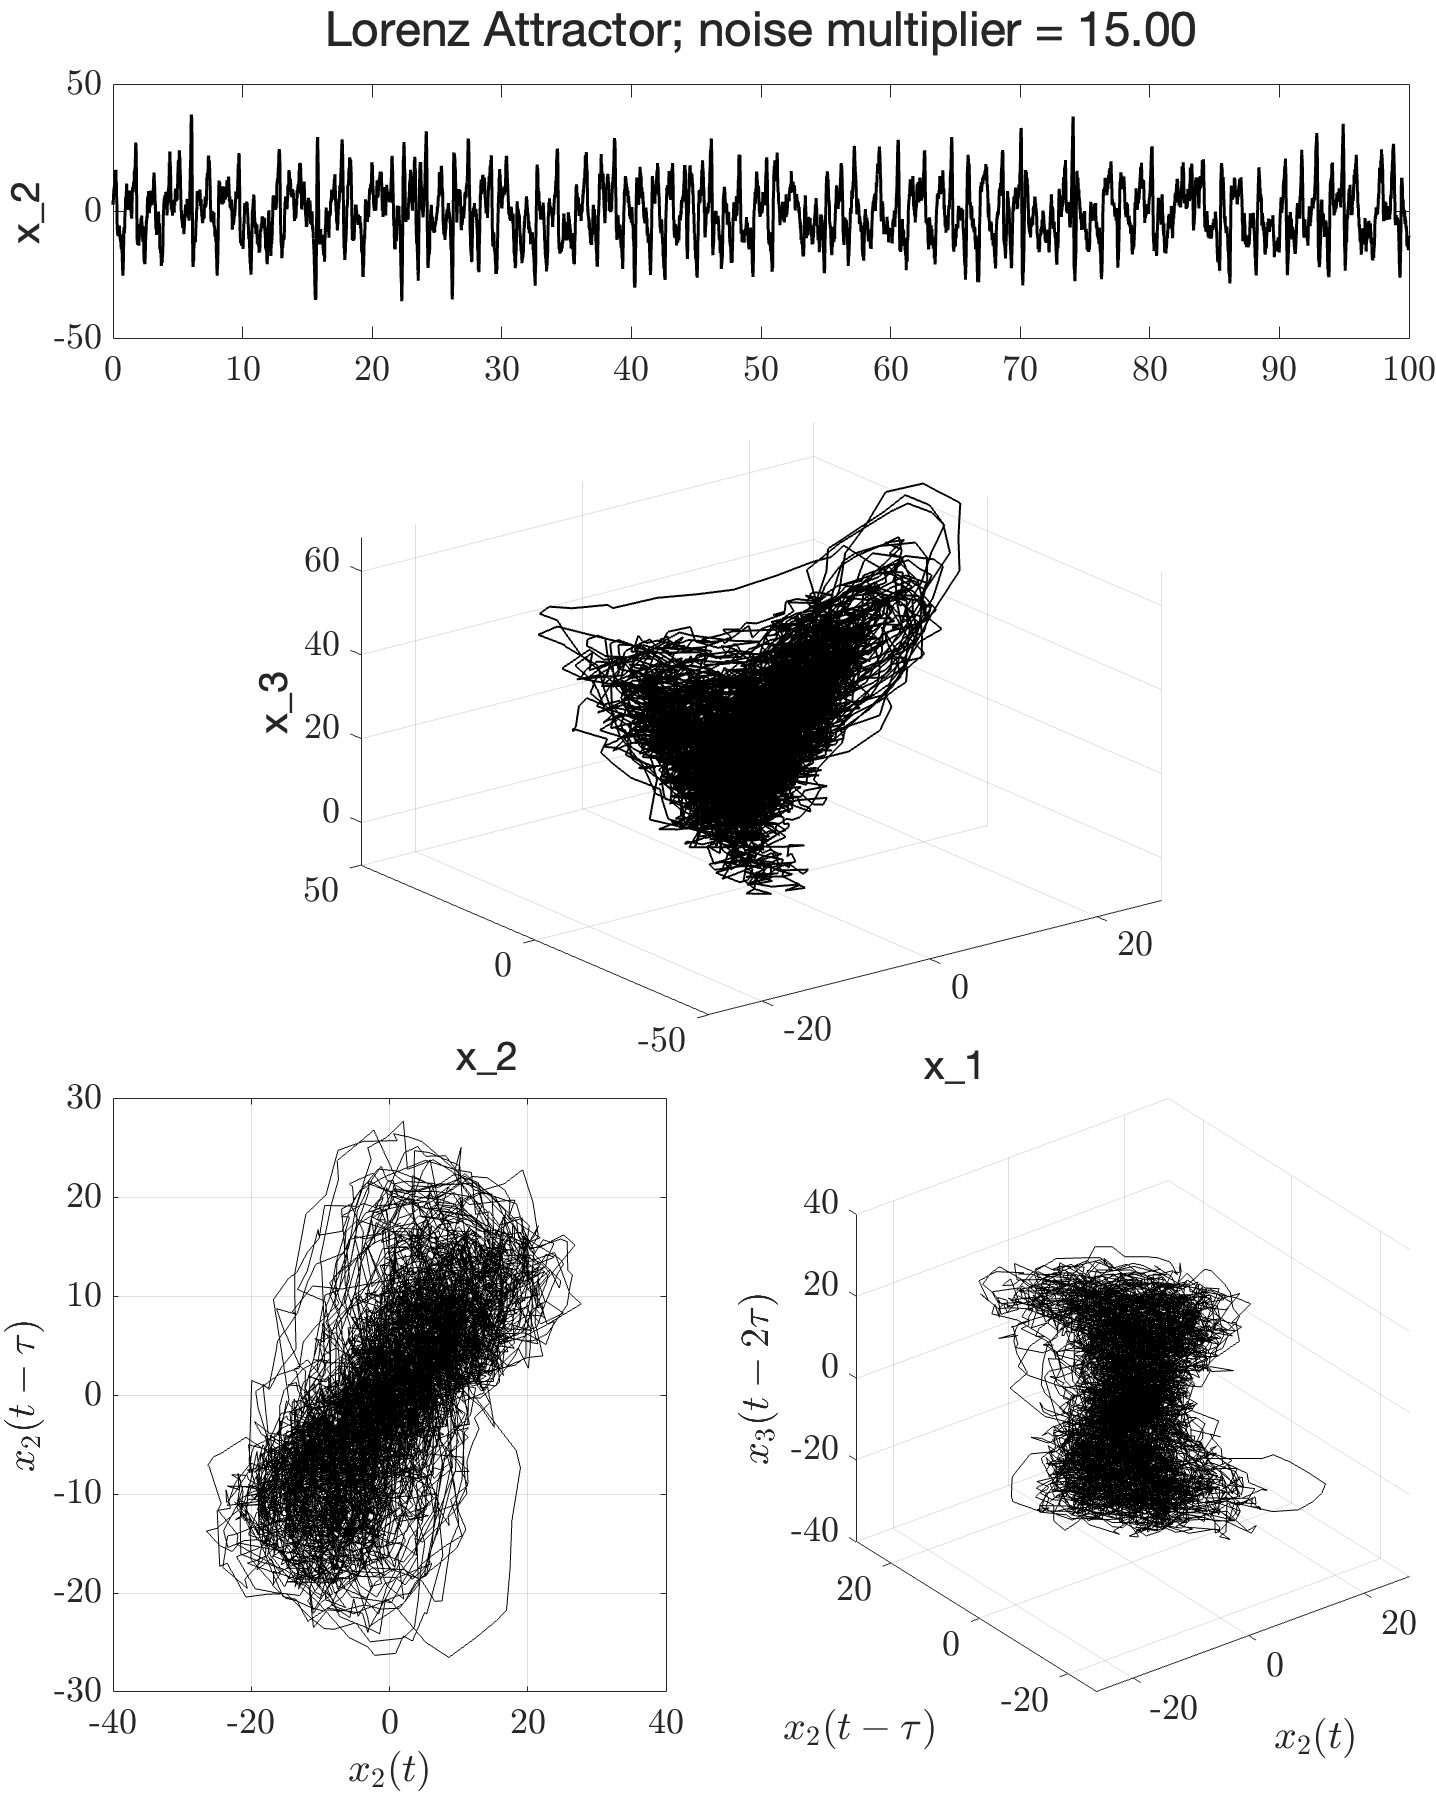

% Extract variables
x1 = X(:,1); % x1 <---> first column 
x2 = X(:,2); % x2 <---> second column
x3 = X(:,3); % x3 <---> third column

% set obervation
y = x1;

% build delay coordinates
[X_delay, ~] = build_delay_coordinates(y, t, s, tau);

figure
lorenz_tiles_noise = tiledlayout(5,6);

% Plot time by x2
nexttile(1, [1 6])
plot(t, x2, ...
    'Color', 'k', ...
    'LineWidth', 1.5)
ylabel('x_2')
ax = gca;
ax.FontSize = 18;

% plot 3D noisy lorenz
nexttile(8,[2 4] )
plot3(x1, x2, x3, ...
      'LineWidth', 1, ...
      'Color', [0 0 0])
grid on
xlabel('x_1')
ylabel('x_2')
zlabel('x_3')
ax = gca;
ax.FontSize = 18;

% plot 2D delay coordinates
nexttile(19,[2 3]);
plot(X_delay(:,1), X_delay(:,2), 'Color', [0 0 0 0.5])
xlabel('$x_2(t)$', 'Interpreter','latex')
ylabel('$x_2(t-\tau)$', 'Interpreter','latex')
grid on
set(gca, 'FontSize', 18)

% plot 3D delay coordinates
nexttile(22,[2 3]);
plot3(X_delay(:,1), X_delay(:,2), X_delay(:,3), 'Color', [0 0 0 0.5])
xlabel('$x_2(t)$', 'Interpreter','latex')
ylabel('$x_2(t-\tau)$', 'Interpreter','latex')
zlabel('$x_3(t-2\tau)$', 'Interpreter','latex')
grid on
set(gca, 'FontSize', 18)
lorenz_tiles_noise.TileSpacing = 'compact';
lorenz_tiles_noise.Title.String = sprintf('Lorenz Attractor; noise multiplier = %0.2f', noise_multiplier);
lorenz_tiles_noise.Title.FontSize = 24;
lorenz_tiles_noise.Padding = 'none';
% get screen size inf
screensize = get( 0, 'ScreenSize');
set(gcf, 'Position', [screensize(3)/2 0 screensize(3)/2 screensize(4)]); clear screensize;

Your own observations aside, hopefully we can agree that in the presence of this level of noise, the underlying structure of the Lorenz attractor is lost with our system observations, and the delayed coordinates did not reveal much more useful information.  Let's think about the Lorenz attractor's properties to help our investigations.

### Task 2.3: Take the Lorenz attractor to have dimension 2 ([it is slightly larger](https://www.sciencedirect.com/science/article/pii/S0167278903004093)).  How many delays should we add to *theoretically* guarantee an embedding (at least in the no-noise case)?

In many instances, it is likely that the underlying manifold's dimension exceeds 2 and 3 dimensions, making it difficult to visualize the manifold.  For example, if we take a manifold with 4-dimensions (in practice, this is not very large), to reconstruct it with an arbitrary observation function would require delay-coordinates larger than $4\times 2 = 8$ dimensions.  As the intrinsic dimension gets large, we can quickly make the data intractable if we embed the data in too high of a space.  This is when we need *reduction *methods to come back down to a tractable space.

Today, we will use the [Singular Value Decomposition](https://en.wikipedia.org/wiki/Singular_value_decomposition) (SVD) algorithm (a good [YouTube video](https://www.youtube.com/watch?v=nbBvuuNVfco)).  Given an $m\times n$ matrix $\mathbf{A}$.  The matrix $\bf{A}$ here can be thought of an organization of data.  In light of how we construct our delay coordinates, the columns of $\bf{A}$ represent system measurements or observations,


$$\mathbf{A} = \left[\mathbf{a}_1, \ \mathbf{a}_2,\, \dots, \ \mathbf{a}_n\right]$$


where $\mathbf{a}_j\in\mathbb{R}^m$ represents the $j^{\text{th}}$ observation made at the $m$ observed time points.  As we add more delayed data, the number of columns of $\bf{A}$ increases.  Our data matrix can be decomposed via the *singular value decomposition*,

$\mathbf{A} = \mathbf{U}\mathbf{\Sigma}\mathbf{V}^T$.

Here, $\mathbf{U}$ is an $m\times m$ matrix, $\mathbf{\Sigma}$ is an $m\times n$ matrix, and $\mathbf{V}$ is an $n\times n$ matrix.  The matrices $\mathbf{U{$ and $\mathbf{V}$ are unitary, meaning the columns of each matrix are orthonormal.  The matrix $\mathbf{\Sigma}$ is a matrix of so-called *singular values*.  Just like with delayed-coordinates, we do not intend to give a total capitulation of the SVD, but we will speak in broad terms with relation to familiar topics from Linear Algebra.

First, singular values roughly coincide with the notion of eigenvalues.  For square-symmetric-real matrices with positive eigenvalues, they exactly coincide.  When ordered, they describe a hierarchy of information encoded in the orthonormal columns of $\mathbf{U}$ and $\mathbf{V}$.  Let's focus on the columns of $\mathbf{U} = [\mathbf{u}_1, \mathbf{u}_2, \dots, \mathbf{u}_m]$.  Since the columns are orthonormal, they can be viewed as a collection of basis vectors ordered according to the associated singular values $\mathrm{diag}(\mathbf{\Sigma})=[\mathbf{\sigma}_1,\mathbf{\sigma}_2,\dots,\mathbf{\sigma}_n]$, (here, I use diagonal loosely, since $\bf{\Sigma}$ is not a diagonal matrix) and are thus organized according to an intrinsic "information containment".  Also, note that $\mathbf{u}_j\in\mathbb{R}^m$, and thus have the *same dimension* as the columns of the original matrix $\bf{A}$.  With this interpretation, the matrix $\mathbf{V}$  describes coefficients required to express the original matrix $\mathbf{A}$ in terms of the basis columns in $\mathbf{U}$.

How will we use the SVD algorithm?  Using built-in functions from matlab, we can calculate these matrices,

`[U,Sigma,V] = svd(A, 'econ')`

We use the `'econ'` argument to only calculate the first $r$ singular values where $r = \min\{m,n\}$.  This keeps the computations tractable.  The matrix A will be a matrix whose rows correspond to timeseries data and columns are the observed (and appended delayed) data.  Thus, for us, the row dimension $m$ will be very large, and the `'econ'` argument prevents calculating and storing large numbers of massive column vectors.

The column dimension $n$ corresponds to the dimension of delayed coordinates.  For example, if we have a single observation and append 4 delays, the matrix A has 5 total columns, and its rows correspond to the sample timepoints.

This poses an interesting addition to delay-coordinates.  In our Lorenz thought-experiment, we would need delay coordinates in $\mathbb{R}^5$ to ensure an embedding, but we can't visualize this embedding.  But we *know* this attractor can exist in three-dimensions.  The SVD gives us an interesting way to use the first 3 columns of $\mathbf{U}$ to visualize embeddings that were first projected to a high-dimensional, visually intractable, space.

#### Prompt 2.3.1 Append 4 delays and set the time-step to 1.  Plot 2 and 3 dimensional representations of your embedded attractors using the SVD.

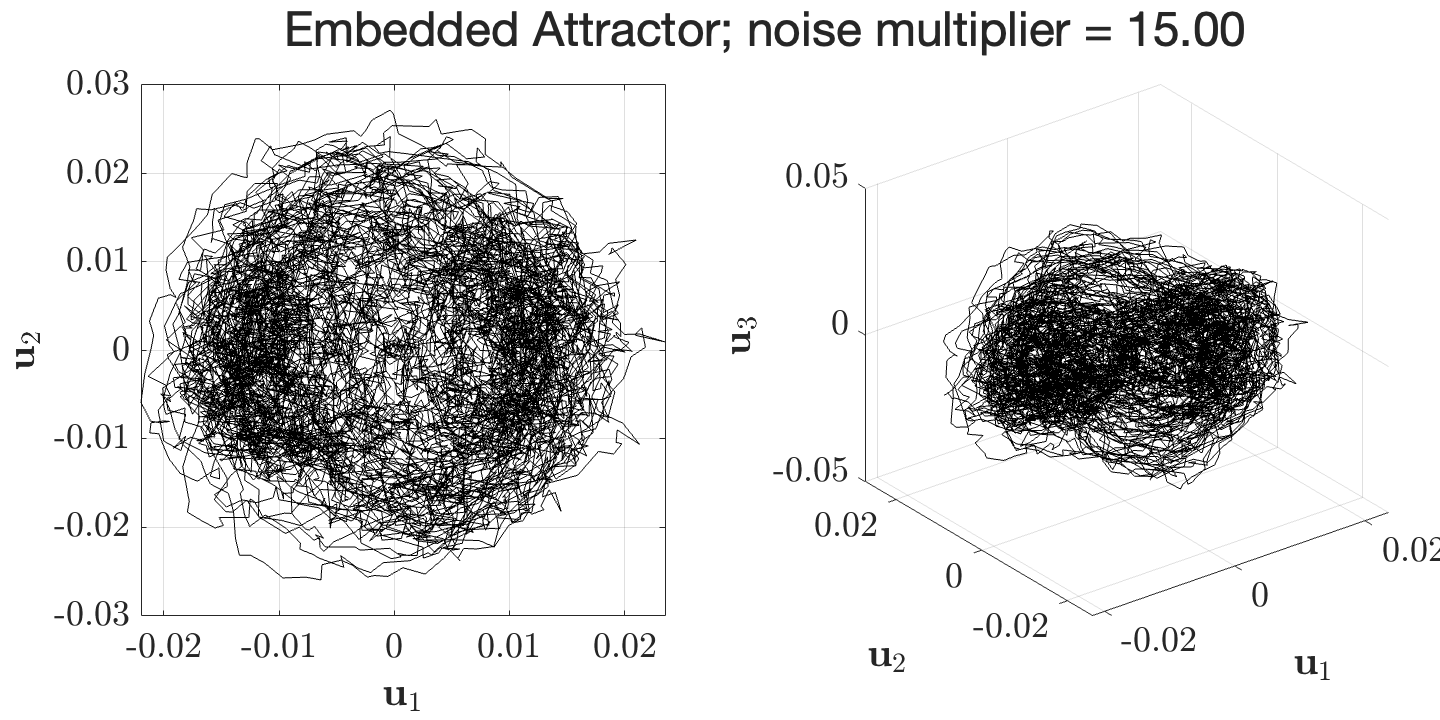

%           Your Code goes Here         %

tau = 10;
s   = 5;

y = x2; % y = g(x1,x2,x3) := x2
[X_delay, ~] = build_delay_coordinates(y, t, s, tau);

% =========================================================================
% matrix A is the matrix of delay coordinats, X_delay
[vecs, vals, modes] = svd( X_delay, 'econ'); vals = diag( vals );

% =========================================================================

figure
svd_tiles = tiledlayout(1,2);

nexttile
plot(vecs(:,1), vecs(:,2), 'Color', [0 0 0 0.5])
xlabel('$\mathbf{u}_1$', 'Interpreter','latex')
ylabel('$\mathbf{u}_2$', 'Interpreter','latex')
grid on
set(gca, 'FontSize', 18)

nexttile
plot3(vecs(:,1), vecs(:,2), vecs(:,3), 'Color', [0 0 0 0.5])
xlabel('$\mathbf{u}_1$', 'Interpreter','latex')
ylabel('$\mathbf{u}_2$', 'Interpreter','latex')
zlabel('$\mathbf{u}_3$', 'Interpreter','latex')
grid on
set(gca, 'FontSize', 18)
svd_tiles.Title.String = sprintf('Embedded Attractor; noise multiplier = %0.2f', noise_multiplier);
svd_tiles.Title.FontSize = 24;
svd_tiles.Padding = 'none';
% get screen size inf
screensize = get( 0, 'ScreenSize');
set(gcf, 'Position', [screensize(3)/2 0 screensize(3)/2 screensize(4)/2.5]); clear screensize;

#### Prompt 2.3.2 Experiment with other values of $s$ and $\tau$.  How does this impact your embeddings?  Are there any choices that do a particularly well?  Why do you think some do better than others?  How can you tell that underlying structure is preserved?

%           Your Code goes Here         %
% some parameter choices that give *reasonable* results
% tau = ...;
% s   = ...; % number of delays

% y = ...; % y = g(x1,x2,x3) := x2
[X_delay, ~] = build_delay_coordinates(y, t, s, tau);

% =========================================================================
% matrix A is the matrix of delay coordinats, X_delay
[vecs, vals, modes] = svd( X_delay, 'econ'); vals = diag( vals );

% =========================================================================

figure
svd_tiles = tiledlayout(1,2);

nexttile
plot(vecs(:,1), vecs(:,2), 'Color', [0 0 0 0.5])
xlabel('$\mathbf{u}_1$', 'Interpreter','latex')
ylabel('$\mathbf{u}_2$', 'Interpreter','latex')
grid on
set(gca, 'FontSize', 18)

nexttile
plot3(vecs(:,1), vecs(:,2), vecs(:,3), 'Color', [0 0 0 0.5])
xlabel('$\mathbf{u}_1$', 'Interpreter','latex')
ylabel('$\mathbf{u}_2$', 'Interpreter','latex')
zlabel('$\mathbf{u}_3$', 'Interpreter','latex')
grid on
set(gca, 'FontSize', 18)
svd_tiles.Title.String = sprintf('Embedded Attractor; noise multiplier = %0.2f', noise_multiplier);
svd_tiles.Title.FontSize = 24;
svd_tiles.Padding = 'none';
% get screen size inf
screensize = get( 0, 'ScreenSize');
set(gcf, 'Position', [screensize(3)/2 0 screensize(3)/2 screensize(4)/2.5]); clear screensize;

## 3 Simulated spikes and theta sequences

You have learned a model that simulates place cells firing with phase precession present.  In this section, we will call code that generates such data with a few input parameters that we can wiggle.  This section is largely open-ended.  Roughly speaking, you should apply techniques we learned in the previous sections to analyze these generated sequences.

I leave it open to what you should be looking for, but keep in mind items of interest (theta oscillations, spikes, precession, rat position on a linear track, ...).  This section roughly replicates the process of an early exploratory analysis of timeseries data.  The data generating function we will call is

`[spM, X, Times, t, position]=build_spike_data_noise( ...inputs...)`

Here `spM` is a matrix, so that `spM(i,j)` gives the timing of the jth spike on the ith cell.  Not every cell will spike an equal number of times, so all cells (except for one) will have `NaN` as placeholders near the final columns of their respective rows (go ahead and look at `spM` in your workspace).

The matrix `X` gives a binning of the spike counts for each cell.  That is, `spM` determines `X` for a fixed bin width.

`Times` gives the starting time for each run up a linear track.  

`t` gives the sampled time according to the bins.

`position` gives the rats position on the linear track.  When it is not moving or completes a pass, the position is reset to zero.  

The inputs match parameters you would have used in `precession.m `plus some others to add in "noise".  They are briefly described in the comments below.

clear; clc; % clear up for this section
% Add paths so we can generate data
addpath( genpath('./dataBuilders') )

% precession parameters
s_ph   = 0.9;      % phase precession controller 1 --> perfect  -1 --> none
sig    = 8;        % width for place cell Gaussian

% *network* set up
nAsC = 20;       % number of representative place cells
nBaC = 10;       % number of background noisy cells

% timing set up 
T = 200;            % Final time in seconds T=200 gives ~ 4 runs
bin_width = 0.001;  % in seconds // 0.001 sec = 1 ms

[spM, X, Times, t, position] = build_spike_data_noise(s_ph, ...
                                  nAsC, ...
                                  nBaC, ...
                                  T, ...
                                  bin_width, ...
                                  sig); 
X = X'; % transpose for building delay coordinates

## 4 Some reflections

When is using delay-coordinates appropriate?

What are drawbacks to delay-coordinates?

How do we try to overcome these drawbacks?

If we start with a low-dimensional observation (like the x-coordinate of lorenz), why even do dimensionality reduction? 

## Some references

If you are interested, here are some links/references to papers that use these techniques at varying degrees in neuroscience (plus some others).

- Time-delay coordinates applied to mice LFP. [Oprisan et al. (2015)](https://www.frontiersin.org/articles/10.3389/fncom.2015.00125/full). [[pdf]](https://core.ac.uk/download/pdf/82859484.pdf)

- Time-delay + SVD to sleep ECoG data. [Brunton et al. (2016)](https://www.sciencedirect.com/science/article/pii/S0165027015003829). [[pdf]](https://www.bingbrunton.com/_files/ugd/b83b01_b8d3f883f7ce4cba976e3961f76a80ef.pdf)

- Time-delay + "nonlinear SVD" to monkey ECoG. [Marrouch et al. (2020)](https://link.springer.com/article/10.1007/s10472-019-09666-2). [[pdf]](https://link.springer.com/content/pdf/10.1007/s10472-019-09666-2.pdf)

- Time-delay + SVD + regression to chaotic systems (like Lorenz). [Brunton et al. (2017)](https://www.nature.com/articles/s41467-017-00030-8). [[pdf]](https://www.nature.com/articles/s41467-017-00030-8.pdf?origin=ppub)

- Time-delay + deep learning (auto encoder). [Gilpin. (2020)](https://proceedings.neurips.cc/paper/2020/hash/021bbc7ee20b71134d53e20206bd6feb-Abstract.html). [[pdf]](https://proceedings.neurips.cc/paper/2020/file/021bbc7ee20b71134d53e20206bd6feb-Paper.pdf)